close all;
clear; clc;
format compact;

links = [5; 5; 5; 5];
initalState = deg2rad([60; -120; 120; -120]);
robot = SerialLinkManipulator(links, initalState);

configuration = [pi/2, -pi/4, pi/4, -pi/4]';

% fv = robot.serialLinkPoly(cspace)
% 
% figure;
% 
% p = patch (fv);
% p.FaceColor = 'red';
% p.EdgeColor = 'none';
% 
% sz = 30;
% axis equal; grid on;
% axis (sz*[-1 1 -1 1]);

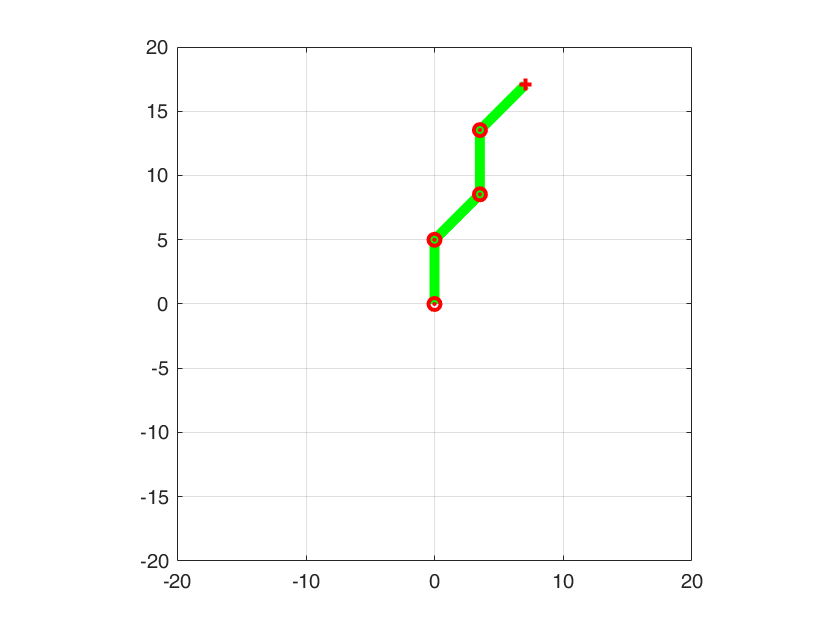

plotSize = 20;
joints = robot.taskSpace(configuration, plotSize);

% pos = [];
% for i = -pi/4:0.05:pi/4+0.1
%     pos = [pos, [pi/2 - i/2; -pi/4 + i/2; pi/4 + i; i]];
% end

% robot.drawConfiguration(pos);

% figure;
% plots = [];
% for i = pos
%     joints = robot.taskSpace(i, false);
% 
%     plot1 = plot(   joints(:, 1), joints(:, 2), ...
%             "LineWidth", 5, "LineStyle", '-', "Color", 'g'  );
%     hold on;
%     plot2 = plot(   joints(1:robot.nJoints, 1), joints(1:robot.nJoints, 2), ...
%             'or', "LineWidth", 2);
%     hold on;
%     plot3 = plot(   joints(end, 1), joints(end, 2), ...
%             '+r', "LineWidth", 2);
%     axis equal; grid on; axis (20*[-1 1 -1 1]);
% 
%     plots = [plot1 plot2 plot3];
%     pause(0.01);
%     delete(plots);
% end

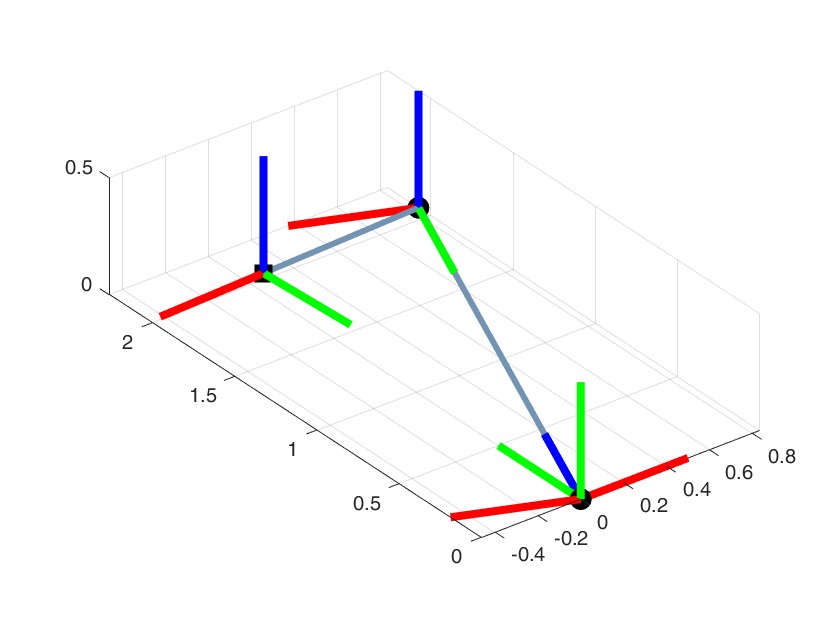

theta = 0;
d1 = 1;
theta2 = -pi/2;

figure;
for t = 1:300
    if t < 100
        theta = t * 0.012;
    
        DH = [  pi/2 + theta,  0, 0,  pi/2 ;
            0, d1, 0,  -pi/2;
            -pi/2 - 0, 0, 0.75, 0];

    elseif t<200
        d1 = 1+(t-100) * 0.0125;
    
        DH = [  pi/2 + theta,  0, 0,  pi/2 ;
            0, d1, 0,  -pi/2;
            -pi/2 - 0, 0, 0.75, 0];
    else
        theta1 = -pi/2 + (t-200)*0.02;
        DH = [  pi/2 + theta,  0, 0,  pi/2 ;
            0, d1, 0,  -pi/2;
            theta1, 0, 0.75, 0];
    end
 
    homogenTF = DHFrames(DH);
    plots = drawFrames(homogenTF, 3, 0.5);

    pause(0.01);

    if t < 300
    delete(plots);
    clear plots;
    end

end

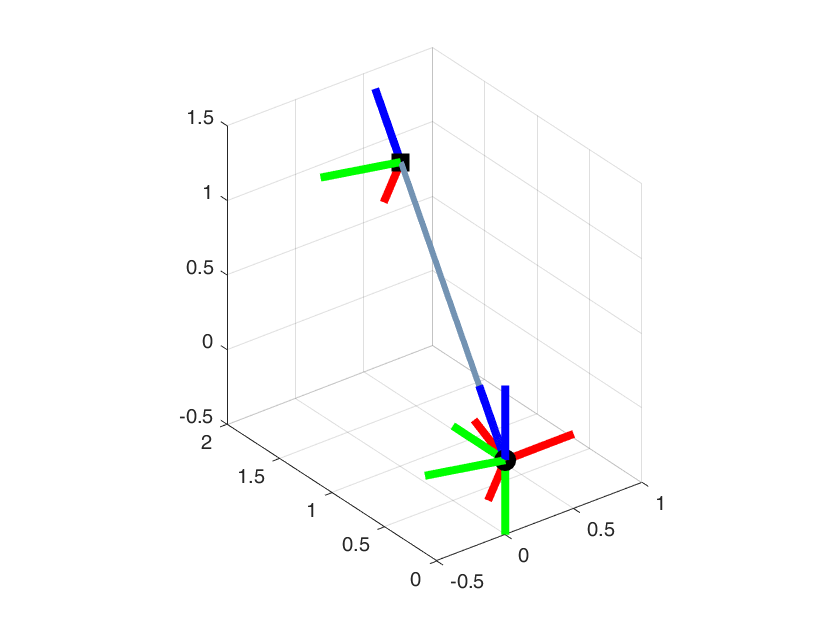

theta = 0;
d1 = 1;
theta2 = 0;

figure;
for t = 1:300
    if t < 100
        theta = t * 0.013;
    
        DH = [  theta,  0, 0,  -pi/2 ;
            theta2, 0, 0,  pi/2;
            0, d1, 0, 0];

    elseif t<200
                theta2 = (t-100)*0.01;
        DH = [  theta,  0, 0,  -pi/2 ;
            theta2, 0, 0,  pi/2;
            0, d1, 0, 0];

    else
        d1 = 1 + (t-200) * 0.01;
    
        DH = [  theta,  0, 0,  -pi/2 ;
            theta2, 0, 0,  pi/2;
            0, d1, 0, 0];
    end
 
    homogenTF = DHFrames(DH);
    plots = drawFrames(homogenTF, 3, 0.5);

    pause(0.01);

    if t < 300
    delete(plots);
    clear plots;
    end

end

function A = DHFrames(DH)
    nJoints = size(DH, 1);
    A = zeros([4, 4*nJoints]);
    for i = 1:nJoints
%         R_z_theta = [   cos(DH(i, 1)), -sin(DH(i, 1)), 0, 0 ;
%                         sin(DH(i, 1)),  cos(DH(i, 1)), 0, 0 ;
%                                     0,              0, 1, 0 ;
%                                     0,              0, 0, 1 ];
%         
%         Trans_z_d = [   1,      0,      0,      0       ;
%                         0,      1,      0,      0       ;
%                         0,      0,      1,   DH(i, 2)   ;
%                         0,      0,      0,      1       ];
% 
%         Trans_x_a = [   1,      0,      0,   DH(i, 3)   ;
%                         0,      1,      0,      0       ;
%                         0,      0,      1,      0       ;
%                         0,      0,      0,      1       ];
% 
%         R_x_alpha = [   1,      0,              0,          0 ;
%                         0, cos(DH(i, 4)), -sin(DH(i, 4)),   0 ;
%                         0, sin(DH(i, 4)),  cos(DH(i, 4)),   0 ;
%                         0,      0,              0,          1 ];
% 
%         A(:, ((4*i)-3):(4*i)) = R_z_theta*Trans_z_d*Trans_x_a*R_x_alpha;

        A(:, ((4*i)-3):(4*i)) = ...
            [   cos(DH(i, 1)), -sin(DH(i, 1))*cos(DH(i, 4)),  sin(DH(i, 1))*sin(DH(i, 4)), DH(i, 3)*cos(DH(i, 1)) ;
                sin(DH(i, 1)),  cos(DH(i, 1))*cos(DH(i, 4)), -cos(DH(i, 1))*sin(DH(i, 4)), DH(i, 3)*sin(DH(i, 1)) ;
                            0,                sin(DH(i, 4)),                cos(DH(i, 4)),               DH(i, 2) ;
                            0,                            0,                            0,                      1 ];
    end
end


function plots = drawFrames(tf, N, axLength)
    tf_inB = zeros(size(tf));
    tempTF = eye(4);
    for n = 1:N
        tf_inB(:, 4*n-3:4*n) = tempTF * tf(:, 4*n-3:4*n);
        tempTF = tf_inB(:, 4*n-3:4*n);
    end


    O = zeros([3, N+1]);
    X = zeros([3, N+1]);
    Y = zeros([3, N+1]);
    Z = zeros([3, N+1]);

    o = [0; 0; 0];
    i = axLength*[1; 0; 0];
    j = axLength*[0; 1; 0];
    k = axLength*[0; 0; 1];

    X(:, 1) = i;
    Y(:, 1) = j;
    Z(:, 1) = k;

    for n = 1:N
        temp = tf_inB(:,4*n-3:4*n) * [o, i, j, k; 1, 1, 1, 1];
        O(:, n+1) = temp(1:3, 1);
        X(:, n+1) = temp(1:3, 2);
        Y(:, n+1) = temp(1:3, 3);
        Z(:, n+1) = temp(1:3, 4);
    end


%     figure;

    plt4 = plot3(O(1,:), O(2,:), O(3,:), "-", LineWidth=3, Color="#7393B3");
    hold on;
    plt5 = plot3(O(1,1:N), O(2,1:N), O(3,1:N), "o", LineWidth=5, Color='black');
    hold on;
    plt6 = plot3(O(1,N+1), O(2,N+1), O(3,N+1), "square", LineWidth=5, Color='black');

        plots = [ plt4, plt5, plt6];
    for n = 1:N+1
        plt1 = plot3([O(1, n), X(1, n)], [O(2, n), X(2, n)], [O(3, n), X(3, n)], LineWidth=4, Color='red');
        hold on;
        plt2 = plot3([O(1, n), Y(1, n)], [O(2, n), Y(2, n)], [O(3, n), Y(3, n)], LineWidth=4, Color='green');
        hold on;
        plt3 = plot3([O(1, n), Z(1, n)], [O(2, n), Z(2, n)], [O(3, n), Z(3, n)], LineWidth=4, Color='blue');
        hold on;

        plots = [plots, plt1, plt2, plt3];
    end

    grid on;
    axis equal;
    xlim([-0.5, 1]); ylim([0,2]); zlim([-0.5,1.5]);
%     view([0, 90]);


end